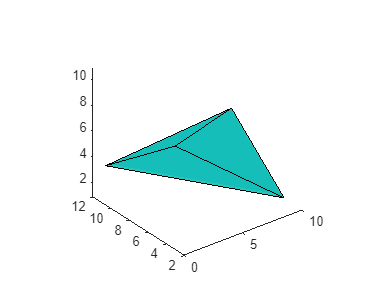

A = [10, 4, 1];
B = [1, 12, 3];
C = [4, 2, 11];
D = [0, 3, 9];

X = [A; B; C; D];
T = [1, 2, 3, 4];

tetramesh(T, X)


n1 = cross((B - A), (C - A))

n1 =     84    78    66


d1 = -1 * (n1(1) * A(1) + n1(2) * A(2) + n1(3) * A(3))

d1 = -1218


n2 = cross((B - A), (D - A))

n2 =     66    52    89


d2 = -1 * (n2(1) * A(1) + n2(2) * A(2) + n2(3) * A(3))

d2 = -957


n3 = cross((C - A), (D - A))

n3 =     -6   -52   -14


d3 = -1 * (n3(1) * A(1) + n3(2) * A(2) + n3(3) * A(3))

d3 = 282


n4 = cross((C - B), (D - B))

n4 =     12   -26   -37


d4 = -1 * (n4(1) * B(1) + n4(2) * B(2) + n4(3) * B(3))

d4 = 411


syms x y z;
f = abs(n1(1) * x + n1(2) * y + n1(3) * z + d1) / sqrt(n1(1) ^ 2 + n1(2) ^ 2 + n1(3) ^ 2) + ...
    abs(n2(1) * x + n2(2) * y + n2(3) * z + d2) / sqrt(n2(1) ^ 2 + n2(2) ^ 2 + n2(3) ^ 2) + ...
    abs(n3(1) * x + n3(2) * y + n3(3) * z + d3) / sqrt(n3(1) ^ 2 + n3(2) ^ 2 + n3(3) ^ 2) + ...
    abs(n4(1) * x + n4(2) * y + n4(3) * z + d4) / sqrt(n4(1) ^ 2 + n4(2) ^ 2 + n4(3) ^ 2);

% TODO